# **Tutorial**

# **Determine numerical characteristics of a stoichiometric matrix**

**Laurent Heirendt**

This tutorial serves as a reference to determine the numerical properties of a stoichiometric matrix and to explore its mathematical properties.

% install spyc
addpath(genpath(pwd))

% install The COBRA Toolbox
addpath(genpath('~/work/git/hub/cobratoolbox'))

% define the filename of the model
modelFile = 'Abiotrophia_defectiva_ATCC_49176.mat';

% define the name of model structure
modelName = 'model';

% define the fieldname of the stoichiometric matrix
matrixName = 'S';

% define a counter of the model
iModel = 1; 

% show and save plots
showPlots = true;
savePlots = false;

## Load the stoichiometric matrix

% load the modelName structure from the modelFile
load(modelFile, modelName);

% select the matrix
A = model.S;
if(isfield(model, matrixName) == 1) && strcmp(matrixName, 'A') == 1
    A = model.A;
end

## Basic numerical characteristics

% determine the number of elements in A
Nelem = numel(A);

% determine the number of nonzero elements in A
Nnz = nnz(A);

% determine the number of reactions and metabolites in A
[Nmets, Nrxns] = size(A);

% determine the maximum and minimum values in A
maxVal = full(max(max(A)));
minVal = full(min(min(A)));

% determine the bandwidth of A
bwidth = bandwidth(A);

## Sparsity

% determine the sparsity ratio of A (in percent)
sparsityRatio = (1 - Nnz / Nelem) * 100;

% determine the complementary sparsity ratio (in percent)
compSparsityRatio = 100.0 - sparsityRatio;

% add the number of non-zeros in each column (reaction)
columnDensity = 0;
for i = 1:Nrxns
    columnDensity = columnDensity + nnz(A(:,i));
end

% calculate the arithmetic average number of non-zeros in each column
columnDensity = columnDensity / Nrxns;

% determine the density proportional to the length of the column
columnDensity = columnDensity / Nmets * 1e6; % [ppm]

## Sparsity Pattern (spy plot)

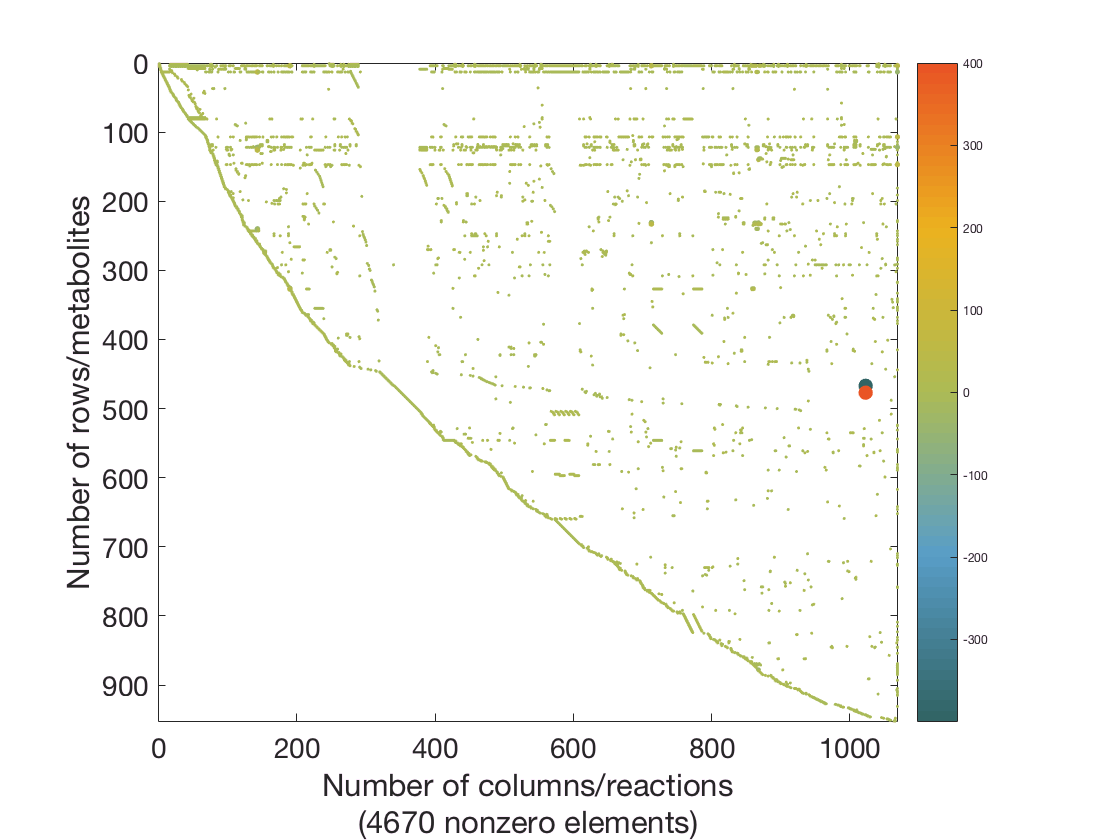

if showPlots
    % define a colormap
    if exist('AdvancedColormap', 'file') == 2
        cmap = AdvancedColormap('proposal');
    end

    % define the name of the output
    outfile = strcat(modelName, matrixName, num2str(iModel));
    
    % print a colorful spy map of the S matrix
    if exist('cmap', 'var') == 1 && exist('spyc', 'file') == 2
        spyc(A, colormap(cmap));
    else
        spy(A);
    end
    
    % set the font size
    fig = gcf;
    ax = fig.CurrentAxes;
    ax.FontSize = 14;
    if savePlots
        set(gcf, 'Visible','off')
        hold off
        saveas(gcf, outfile, 'epsc');
    end
end

## Rank

% determine the rank of the stoichiometric matrix
[rankA,p,q] = getRankLUSOL(A);

% calculate the rank deficiency ratio
rankDeficiencyA = 1 - rankA/min(Nmets, Nrxns);

## Singular Values and Condition Number

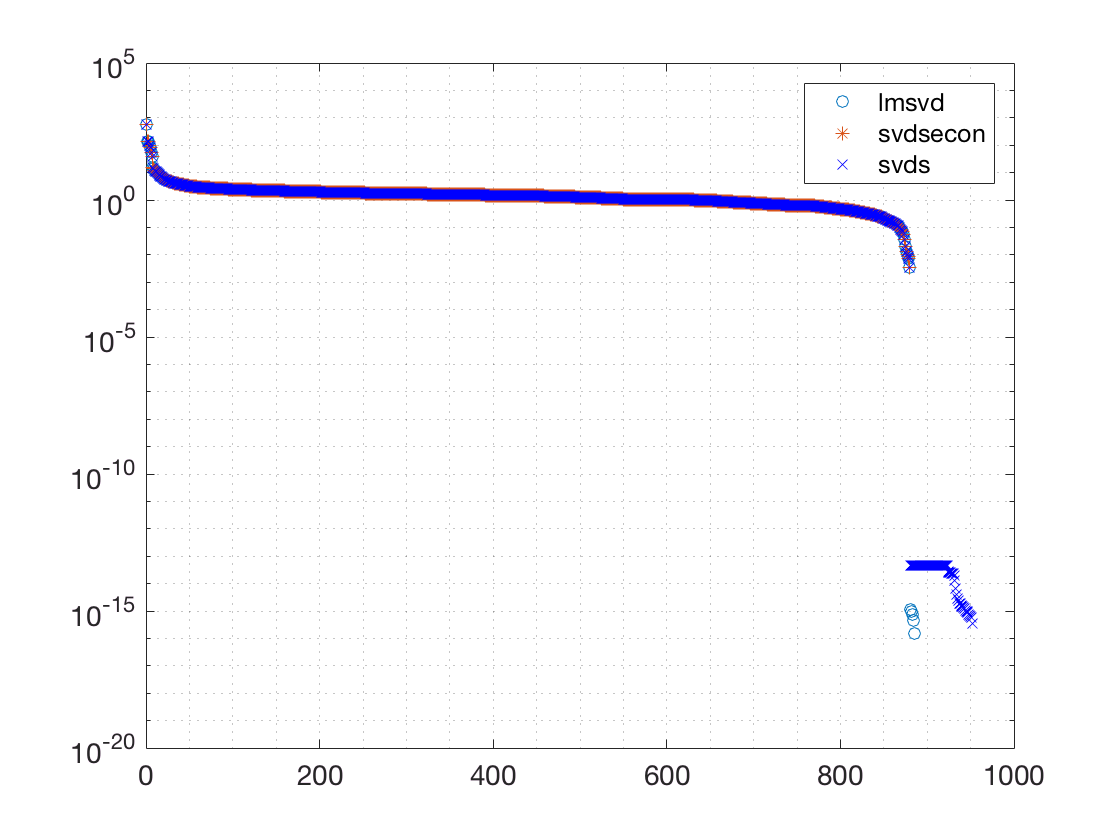

% calculate the singular values

[~, ss, ~] = lmsvd(A, rankA + 5, []);
svVect = diag(ss);

[~, ss, ~] = svdsecon(A, rankA);
svVect1 = diag(ss);

svVect2 = svds(A, min(Nmets, Nrxns));

if showPlots
    %plot the singular values
    figure;
    
    % plot singular values obtained using lmsvd
    semilogy(linspace(1, length(svVect), length(svVect)), svVect, 'o');
    hold on;
    
    % plot singular values obtained using svdsecon
    semilogy(linspace(1, length(svVect1), length(svVect1)), svVect1, '*');
    
    % plot singular values obtained using svds
    semilogy(linspace(1, length(svVect2), length(svVect2)), svVect2, 'bx');
    
    legend('lmsvd', 'svdsecon', 'svds')
    grid minor;
    fig = gcf;
    ax = fig.CurrentAxes;
    ax.FontSize = 14;
end


% determine the maximum and minimum singular values
maxSingVal = max(svVect);
minSingVal = svVect(rankA)

minSingVal = 0.0034

maxSingVal1 = max(svVect1);
minSingVal1 = svVect1(rankA)

minSingVal1 = 0.0034

maxSingVal2 = svds(A, 1);
minSingVal2 = svds(A, 1, 'smallestnz')

minSingVal2 = 0.0034


% determine the condition number
condNumber = maxSingVal/minSingVal;

## Summary of model characteristics

fprintf(['SUMMARY ---------------------------- Model #%d\n',...
        'Model file/Model name/Matrix name    %s/%s/%s\n',...
        'Size is [Nmets, Nrxns]               [%d, %d]\n',...
        'Number of elements:                  %d \n',...
        'Number of nonzero elements:          %d \n',...
        'Sparsity ratio [%%]:                  %1.2f \n',...
        'Bandwidth:                           %d \n',...
        'Maximum value:                       %d \n',...
        'Minimum value:                       %d \n',...
        'Column density [ppm]:                %1.2f \n',...
        'Rank:                                %d \n',...
        'Rank deficiency ratio [%%]:           %1.2f \n',...
        'Maximum singular value:              %1.2f \n',...
        'Minimum singular value:              %1.2f \n',...
        'Condition number:                    %1.2f \n',...
        ],...
        iModel, modelFile, modelName, matrixName, Nmets, ...
        Nrxns, Nelem, Nnz, sparsityRatio, ...
        bwidth, maxVal, minVal, columnDensity, rankA, rankDeficiencyA, ...
        maxSingVal, minSingVal, condNumber);

SUMMARY ---------------------------- Model #1
Model file/Model name/Matrix name    Abiotrophia_defectiva_ATCC_49176.mat/model/S
Size is [Nmets, Nrxns]               [952, 1069]
Number of elements:                  1017688 
Number of nonzero elements:          4670 
Sparsity ratio [%]:                  99.54 
Bandwidth:                           162 
Maximum value:                       400 
Minimum value:                       -399 
Column density [ppm]:                4588.83 
Rank:                                880 
Rank deficiency ratio [%]:           0.08 
Maximum singular value:              564.98 
Minimum singular value:              0.00 
Condition number:                    165063.48 
